# Two-link planar Impedance Control

## Objective:

 Implement impednace controller with and without Force/Torque sensor (F/T) in task space.

## **prerequisite:**

- Completed joint control simulation `Two_task_control.mlx`.

- Understands the theory behind different Control strategies and inverse/forward kinematics.

- Understands the theory of force/impedance control and different approaches used

clc;
clear;

## Background

**Jacobian matrix**

syms t L_1 L_2 theta_1(t) theta_2(t)
% analtical jacobian (same as geometric jacobian for 2R robot)
J = [
       -L_1.*sin(theta_1)-L_2.*sin(theta_1+theta_2) , -L_2.*sin(theta_1+theta_2) ;
        L_1.*cos(theta_1)+L_2.*cos(theta_1+theta_2) ,  L_2.*cos(theta_1+theta_2) ;
    ];

### Environment model

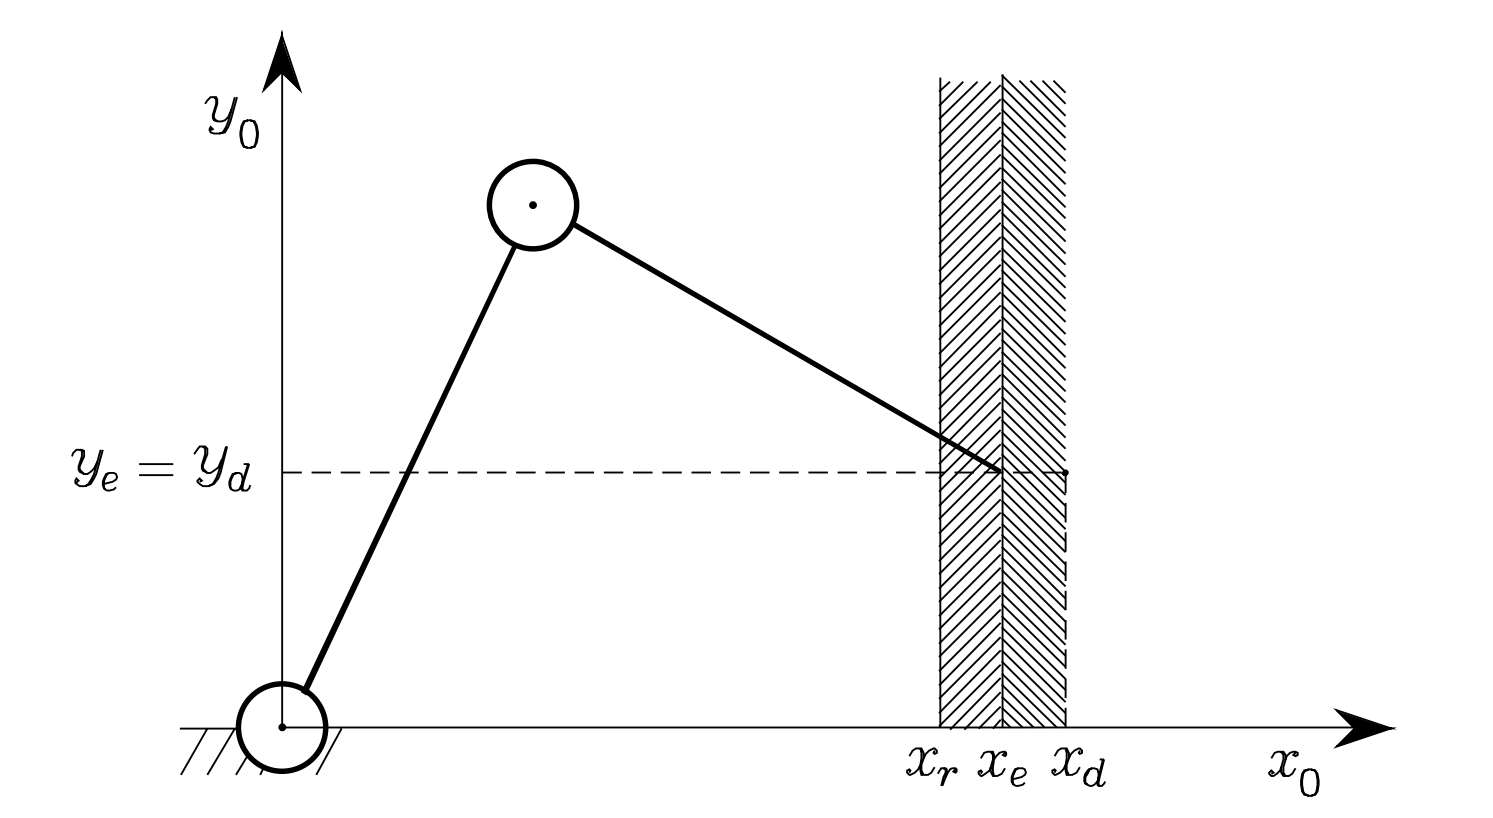

Environment is modelled as a spring with stiffness Kr.


$$F_{\textrm{env}} =K_r \Delta x\;$$


- Kr=10^6 in Raibert & Craig paper (Hybrid position/force control of manipulators 1981)

% Parameters for different environments
%  - wall position Xenv away with width W_env
%  - Cylinder
%  - nonuniform shape with sharp edges
Xenv = 0.45; % Env X offset in meter
W_env = 0.42; % env Y width in meter
R_env = 0.3; % env radius in meter (for curved env)

Ke_s = 9*10^5; % environment stiffness N/m (stiff)
Ke_d = 0.1; % environment damping 

### Impedance control (with F/T sensor)

#### General impedance form

#### 
$$\mathit{\mathbf{F}}\;={\mathit{\mathbf{M}}}_{t\;} \left({\ddot{\mathit{\mathbf{x}}} }_d -\ddot{\mathit{\mathbf{x}}} \right){+\mathit{\mathbf{K}}}_P \left({\mathit{\mathbf{x}}}_d -\mathit{\mathbf{x}}\right)+{\mathit{\mathbf{K}}}_D \left({\dot{\mathit{\mathbf{x}}} }_d -\dot{\mathit{\mathbf{x}}} \right)$$


#### Linearize Feedback:

#### 
$$\;u=M\left(q\right)\mathit{\mathbf{a}}+C\left(q,\dot{\;q} \right)\dot{\;\mathit{\mathbf{q}}} +g\left(q\right)-J^T F$$


#### Linear Impedance control:

#### 
$$\;\mathit{\mathbf{a}}=J^{-1} \left(\underset{\textrm{feedforward}\;\textrm{acc}}{\underbrace{\ddot{{\mathit{\mathbf{x}}}_d } } } -\underset{\textrm{coupling}}{\underbrace{\dot{J} \dot{q} } } +M_t^{-1} \left\lbrace \underset{\textrm{Impedance}}{\underbrace{K_P \left({\mathit{\mathbf{x}}}_d -\mathit{\mathbf{x}}\right)+K_D \left({\dot{\mathit{\mathbf{x}}} }_d -\dot{\mathit{\mathbf{x}}} \right)} } +\underset{\textrm{weighted}\;\textrm{contact}\;\textrm{force}}{\underbrace{F} } \;\right\rbrace \right)$$


- If Force measurement is noisy (like in this simulation), it is better to omit the weighted contact force term (as in our simulation)

### 
$$\;a=J^{-1} \left(\underset{\textrm{feedforward}\;\textrm{acc}}{\underbrace{\ddot{{\mathit{\mathbf{x}}}_d } } } -\underset{\textrm{coupling}}{\underbrace{\dot{J} \dot{q} } } +M_t^{-1} \left\lbrace \underset{\textrm{Impedance}}{\underbrace{K_P \left({\mathit{\mathbf{x}}}_d -\mathit{\mathbf{x}}\right)+K_D \left({\dot{\mathit{\mathbf{x}}} }_d -\dot{\mathit{\mathbf{x}}} \right)} } \right\rbrace \right)$$


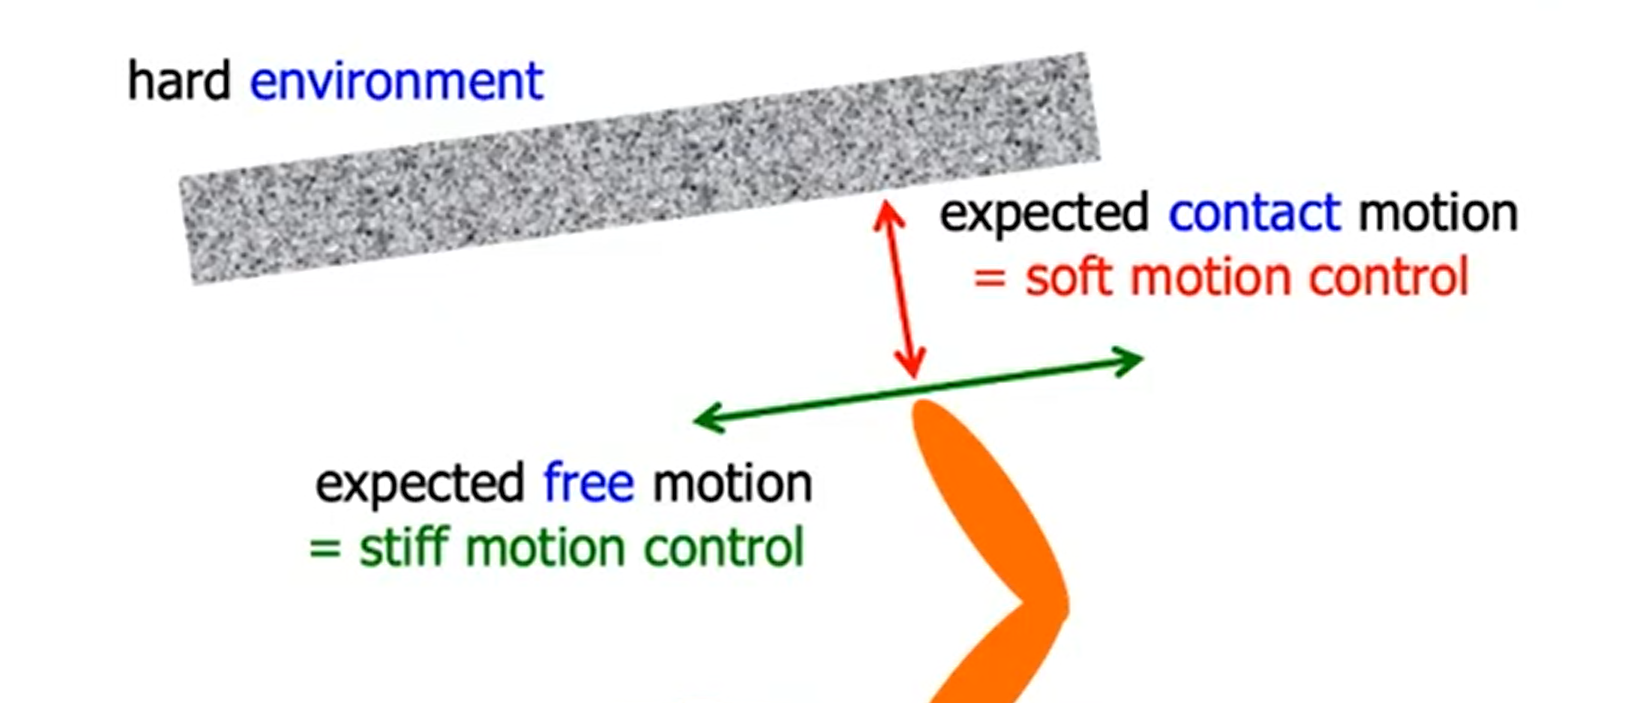

- **Constrained directions: **large $M_{t,i}$and small $K_{P,i}$ (low contact forces)

- **Free motion directions: **small $M_{t,i}$and large $K_{P,i}$ (good tracking)

- $K_{D,i}$ (damping coefficients) shapes the transient behaviors

### Impedance control (without F/T sensor)

- Assume apparent inertia equals to natural cartesian inertia (${\mathit{\mathbf{M}}}_{\mathit{\mathbf{x}}} ={\mathit{\mathbf{M}}}_{\mathit{\mathbf{m}}}$)

#### Control law with linearized Feedback:

#### 
$$\;u=M\left(q\right)\mathit{\mathbf{a}}+C\left(q,\dot{\;q} \right)\dot{\;\mathit{\mathbf{q}}} +g\left(q\right)+J^T \left\lbrace \underset{\textrm{Impedance}}{\underbrace{K_P \left({\mathit{\mathbf{x}}}_d -\mathit{\mathbf{x}}\right)+K_D \left({\dot{\mathit{\mathbf{x}}} }_d -\dot{\mathit{\mathbf{x}}} \right)} } \right\rbrace$$


### 
$$\;\mathit{\mathbf{a}}=J^{-1} \left(\underset{\textrm{feedforward}\;\textrm{acc}}{\underbrace{\ddot{{\mathit{\mathbf{x}}}_d } } } -\underset{\textrm{coupling}}{\underbrace{\dot{J} \dot{q} } } \right)$$


## Running the simulations

Multiple controllers are simulated as variant subsystems. i.e. you can select which controller to run in each simulation. This also goes for robot model and trajectory commands.

### Import robot parameters

run('sim_params_force.m');

### Impedance control

% Impedance control parameters
Mt  = [ 2 0.3]; 
Mt_inv = 1./(Mt);
Kpt = [400 300];
Kdt = [40 35];

### Open simulation

open_system("sim_4_twolink_impedance_control.slx")

# References

[1] Robotics Modelling, Planning and Control  by Bruno Siciliano, Lorenzo Sciavicco, Luigi Villani, and Giuseppe Oriolo  

[2] Robotics 2 - Impedance Control, [https://www.youtube.com/watch?v=IolG5V_skv8&list=PLQ61-pGTCGHJbwR7ItM5cWN0-DI33FZFE&index=14](https://www.youtube.com/watch?v=IolG5V_skv8&list=PLQ61-pGTCGHJbwR7ItM5cWN0-DI33FZFE&index=14)